clear all
close all

filename= 'cluster_group.tsv';
data = readtable(filename, 'FileType', 'text', 'Delimiter', '\t', 'ReadVariableNames', true);

id_vector = data.cluster_id;
group_vector = string(data.group);

% Szűrés: csak a "good" értékű sorokat tartom meg
filter_idx = (group_vector == "good"); 
id_good = id_vector(filter_idx);

%2. rész

spike_times = readtable('spike_times.tsv', 'FileType', 'text', 'Delimiter', '\t');
spike_t = table2array(spike_times);

spike_clusters= readtable('spike_clusters.tsv', 'FileType', 'text', 'Delimiter', '\t');
spike_id = table2array(spike_clusters);

spike_matrix= [spike_id, spike_t];

mask = ismember(spike_matrix(:, 1), id_good);
spike_good = spike_matrix(mask, :);

% Egyedi ID-k kinyerése (az ID-k nem ismétlődnek)
unique_ids = unique(spike_good(:,1));  

% Tároló inicializálása (cellatömb)
grouped_data = cell(length(unique_ids), 2);

% Csoportosítás ID-k szerint
for i = 1:length(unique_ids)
    id = unique_ids(i);  % Az aktuális ID
    grouped_data{i,1} = id;  % Az ID eltárolása
    grouped_data{i,2} = spike_good(spike_good(:,1) == id, 2)';  % Az összes hozzá tartozó időpillanat vektorban
end


%2.hét

data = readtable('metrics.csv', 'Delimiter', ',');

%good

metrics_good= data(ismember(data.Var1, id_good), :);

%Ac szerint szűrés
metrics_ac = metrics_good(~isnan(metrics_good.amplitude_cutoff), :); 
metrics_ac= metrics_ac(metrics_ac.amplitude_cutoff<=0.01,:);

%Isi ratio

metrics_isi= metrics_ac((metrics_ac.isi_violations_ratio <= 2), :);

%Pr
metrics_pr= metrics_isi(metrics_isi.presence_ratio>=0.9,:);

%Vegleges id-k
mask = ismember([grouped_data{:,1}], metrics_pr.Var1);

% Szűrt adatok kinyerése
spike_all = grouped_data(mask,:);


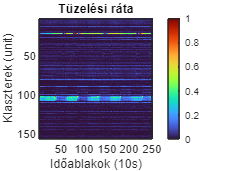

%3.het
% Paraméterek
sampling_rate = 30000;              % Mintavételezési ráta (Hz)
duration_min = 42;                  % Teljes idő (perc)
bin_size = 10 * sampling_rate;      % Bin méret (10s)
n = size(spike_all, 1);     % Klaszterek száma

% Binning
total_samples = duration_min * 60 * sampling_rate;
time_bins = 0:bin_size:total_samples;
m = length(time_bins) - 1;
time_seconds = (time_bins(1:end-1)) / sampling_rate;

% Tüzelési ráta (Hz)
firing_rates = zeros(n, m);
for i = 1:n
    spike_times = spike_all{i,2};
    counts = histcounts(spike_times, time_bins);
    firing_rates(i, :) = counts / 10;
end

fr_norm= rescale(firing_rates);

% Heatmap ábrázolása
figure;
imagesc(fr_norm);
colormap('turbo');  % Kontrasztos színskála
colorbar;  % Színskála hozzáadása
xlabel('Időablakok (10s)');
ylabel('Klaszterek (unit)');
title('Tüzelési ráta');
caxis([0, 1]);

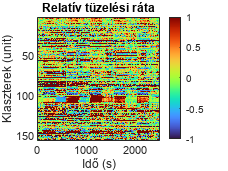


% ON periódusok kezdete (percben → mintavételben)
on_minutes = [2, 10, 18, 26, 34];
on_samples = on_minutes * 60 * sampling_rate;

% Baseline számítás (mindig az ON előtti 2 perc utolsó része)
baseline_matrix = zeros(n, 5);
for j = 1:5
    start = on_samples(j) - 2*60*sampling_rate;
    end_  = on_samples(j);
    idx = (time_bins(1:end-1) >= start) & (time_bins(1:end-1) < end_);
    for i = 1:n
        baseline_matrix(i, j) = mean(firing_rates(i, idx));
    end
end

% Relatív tüzelési ráta mátrix (unit x idő)
relative_fr = zeros(n, m);

% Az első baseline szakasz (0–2 perc → első 12 bin)
first_baseline = baseline_matrix(:,1);  % baseline_1
for i = 1:n
    relative_fr(i, 1:12) = (firing_rates(i, 1:12) - first_baseline(i)) / first_baseline(i);
end

% A többi szakasz (ON-OFF blokkok)
% Az 1. blokk a 2. percnél indul, tehát a 13. bintől (2*60/10 + 1)
start_bin = 2*60 / 10 + 1;
for j = 1:5
    bin_idx = start_bin + (j-1)*48;  % 48 bin = 4 perc ON + 4 perc OFF
    bins = bin_idx : bin_idx + 47;
    for i = 1:n
        baseline = baseline_matrix(i, j);
        relative_fr(i, bins) = (firing_rates(i, bins) - baseline) / baseline;
    end
end

% Ábrázolás
figure;
imagesc(time_seconds, 1:n, relative_fr);
colormap('turbo');
colorbar;
xlabel('Idő (s)');
ylabel('Klaszterek (unit)');
title('Relatív tüzelési ráta');
clim([-1 1]); 

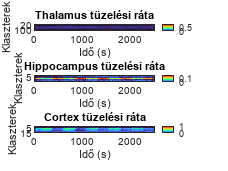

%5.het

% Kinyerjük a spike_all-ból a cluster ID-kat
n = size(spike_all, 1);
spike_ids = zeros(n, 1);
for i = 1:n
    spike_ids(i) = spike_all{i, 1};  % feltételezve, hogy itt van az ID
end

% Beolvasás
cluster_info = readtable('cluster_info.tsv', 'FileType', 'text', 'Delimiter', '\t');

% spike id-k szűrése a cluster_info fájlban
channels= cluster_info(ismember(cluster_info.cluster_id, spike_ids), :);
 
% Agyi régiók indexei
thalamus_idx = find(channels.ch < 65);
hippocampus_idx = find(channels.ch >= 65 & channels.ch <= 151);
cortex_idx = find(channels.ch > 151);

% Szétválogatás
firingRates_thalamus = fr_norm(thalamus_idx, :);
firingRates_hippocampus = fr_norm(hippocampus_idx, :);
firingRates_cortex = fr_norm(cortex_idx, :);

relative_fr_thalamus = relative_fr(thalamus_idx, :);
relative_fr_hippocampus = relative_fr(hippocampus_idx, :);
relative_fr_cortex = relative_fr(cortex_idx, :);

x_seconds = (0:size(firing_rates, 2)-1) * 10;

figure;
subplot(3,1,1);
imagesc(x_seconds, 1:size(firingRates_thalamus, 1), firingRates_thalamus);
title('Thalamus tüzelési ráta');
ylabel('Klaszterek');
xlabel('Idő (s)');
colormap('turbo');
colorbar;

subplot(3,1,2);
imagesc(x_seconds, 1:size(firingRates_hippocampus, 1), firingRates_hippocampus);
title('Hippocampus tüzelési ráta');
ylabel('Klaszterek');
xlabel('Idő (s)');
colormap('turbo');
colorbar;

subplot(3,1,3);
imagesc(x_seconds, 1:size(firingRates_cortex, 1), firingRates_cortex);
title('Cortex tüzelési ráta');
ylabel('Klaszterek');
xlabel('Idő (s)');
colormap('turbo');
colorbar;

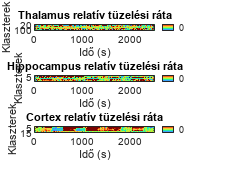


x1_seconds = (0:size(relative_fr, 2)-1) * 10;

%Relativ tözelési ráta agyi régiókra szétválogatva
figure;
subplot(3,1,1);
imagesc(x1_seconds, 1:size(relative_fr_thalamus, 1), relative_fr_thalamus);
title('Thalamus relatív tüzelési ráta');
ylabel('Klaszterek');
xlabel('Idő (s)');
colormap('turbo');
colorbar;
clim([-1 1]);

subplot(3,1,2);
imagesc(x1_seconds, 1:size(relative_fr_hippocampus, 1),relative_fr_hippocampus);
title('Hippocampus relatív tüzelési ráta');
ylabel('Klaszterek');
xlabel('Idő (s)');
colormap('turbo');
colorbar;
clim([-1 1]);

subplot(3,1,3);
imagesc(x1_seconds, 1:size(relative_fr_cortex, 1), relative_fr_cortex);
title('Cortex relatív tüzelési ráta');
ylabel('Klaszterek');
xlabel('Idő (s)');
colormap('turbo');
colorbar;
clim([-1 1]);

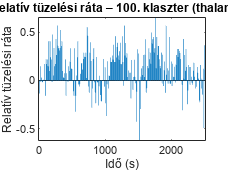


%Oszlopdiagram
cluster_idx = 100; 
cluster_idx1 = 14;
cluster_idx2 = 8;
data = relative_fr_thalamus(cluster_idx, :);
data1 = relative_fr_hippocampus(cluster_idx1, :);
data2 = relative_fr_cortex(cluster_idx2, :);

% Idő tengely másodpercben
x_seconds = (0:length(data)-1) * 10;

% Ábrázolás
figure;
bar(x_seconds, data);
xlabel('Idő (s)');
ylabel('Relatív tüzelési ráta');
title(['Relatív tüzelési ráta – ', num2str(cluster_idx), '. klaszter (thalamus)']);

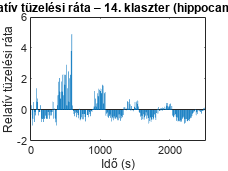


% Ábrázolás
figure;
bar(x_seconds, data1);
xlabel('Idő (s)');
ylabel('Relatív tüzelési ráta');
title(['Relatív tüzelési ráta – ', num2str(cluster_idx1), '. klaszter (hippocampus)']);

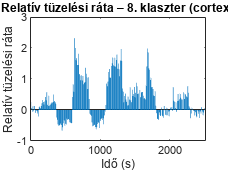


% Ábrázolás
figure;
bar(x_seconds, data2);
xlabel('Idő (s)');
ylabel('Relatív tüzelési ráta');
title(['Relatív tüzelési ráta – ', num2str(cluster_idx2), '. klaszter (cortex)']);